Temps = readtable('Temperaturas.txt');
Temps = table2array(Temps);

Punto 1

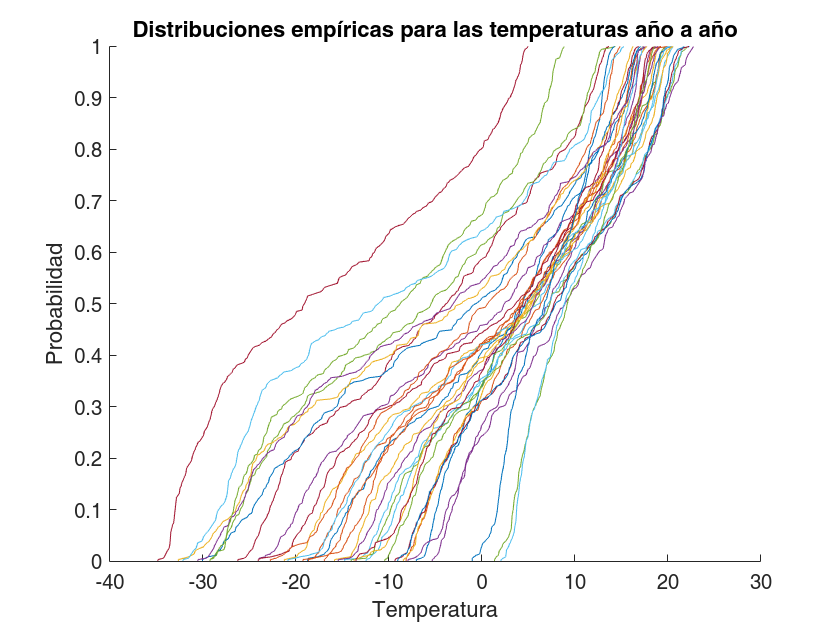

%Distribución empírica
A = zeros(35,1);
hold on
title("Distribuciones empíricas para las temperaturas año a año")
xlabel("Temperatura")
ylabel("Probabilidad")
for i = 1:35
    temp = Temps(:,i);
    [F,t] = ecdf(temp);
    tq1 = t(find(t>=0)); tq2 = t(find(t<0));
    Fq1 = F(find(t>=0)); Fq2 = F(find(t<0));
    A(i) = trapz(tq1,1-Fq1) - trapz(tq2,Fq2);
    plot(t,F)
end

%Tabla de doble entrada con la media

means = mean(Temps,1);

doubletable = zeros(36,36);

doubletable(1,2:36) = means;

doubletable(2:36,1) = means;

for i = 2:36
    for j = 2:36
        valori = means(i-1);
        valorj = means(j-1);
        doubletable(i,j) = i-1;
        if valorj > valori
            doubletable(i,j) = j-1;
        end
       
        if i == j
            doubletable(i,j) = 0; 
        end

         

    end
end

array2table(doubletable)

ans = 36×36 table
    doubletable1    doubletable2    doubletable3    doubletable4    doubletable5    doubletable6    doubletable7    doubletable8    doubletable9    doubletable10    doubletable11    doubletable12    doubletable13    doubletable14    doubletable15    doubletable16    doubletable17    doubletable18    doubletable19    doubletable20    doubletable21    doubletable22    doubletable23    doubletable24    doubletable25    doubletable26    doubletable27    doubletable28    doubletable29    <

%Tabla de doble entrada con la estimación empírica de la media
means = A'

means =    11.6286   14.1814   13.8433   12.0464   15.5641   17.5864   21.0584   21.7164   21.3612   19.8023   19.4401   20.0478   20.4314   16.4929   16.2411   19.2790   23.5851   23.7625   22.0258   23.4555   24.6000   26.4963   20.8197   17.6123   16.5756    8.5010    7.4666   17.2632    7.9467   21.7653   27.7195   25.3837   19.4678   22.7664   18.1982


doubletable = zeros(36,36);

doubletable(1,2:36) = means;

doubletable(2:36,1) = means;

for i = 2:36
    for j = 2:36
        valori = means(i-1);
        valorj = means(j-1);
        doubletable(i,j) = i-1;
        if valorj > valori
            doubletable(i,j) = j-1;
        end
       
        if i == j
            doubletable(i,j) = 0; 
        end

         

    end
end

array2table(doubletable)

ans = 36×36 table
    doubletable1    doubletable2    doubletable3    doubletable4    doubletable5    doubletable6    doubletable7    doubletable8    doubletable9    doubletable10    doubletable11    doubletable12    doubletable13    doubletable14    doubletable15    doubletable16    doubletable17    doubletable18    doubletable19    doubletable20    doubletable21    doubletable22    doubletable23    doubletable24    doubletable25    doubletable26    doubletable27    doubletable28    doubletable29    <

Punto 2

temp = Temps(:,1);
[F,t] = ecdf(temp);
tq1 = t(find(t>=0)); tq2 = t(find(t<0));
Fq1 = F(find(t>=0)); Fq2 = F(find(t<0));
estimator = trapz(tq1,1-Fq1) - trapz(tq2,Fq2)

estimator = 4.6625

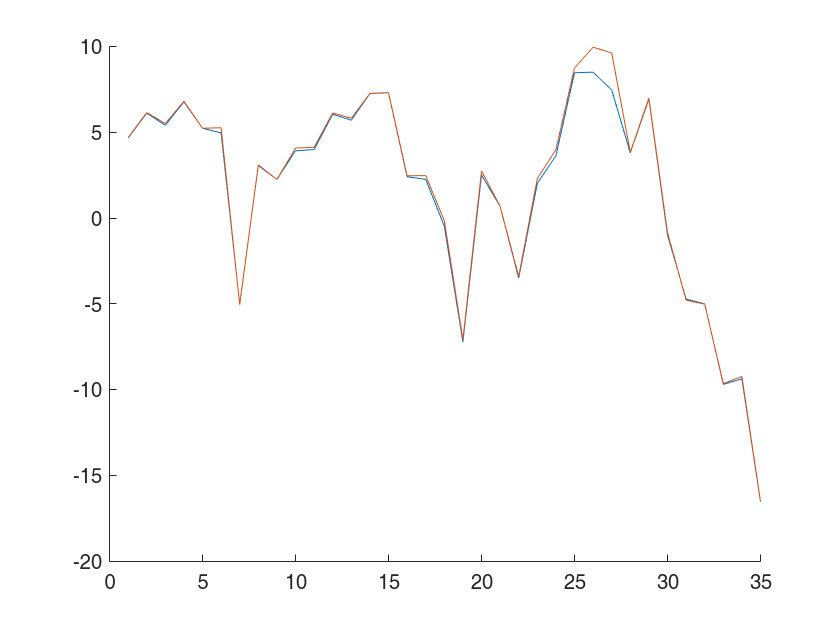

clf
hold on
plot(1:35,A)
plot(1:35, mean(Temps,1))

Punto 3

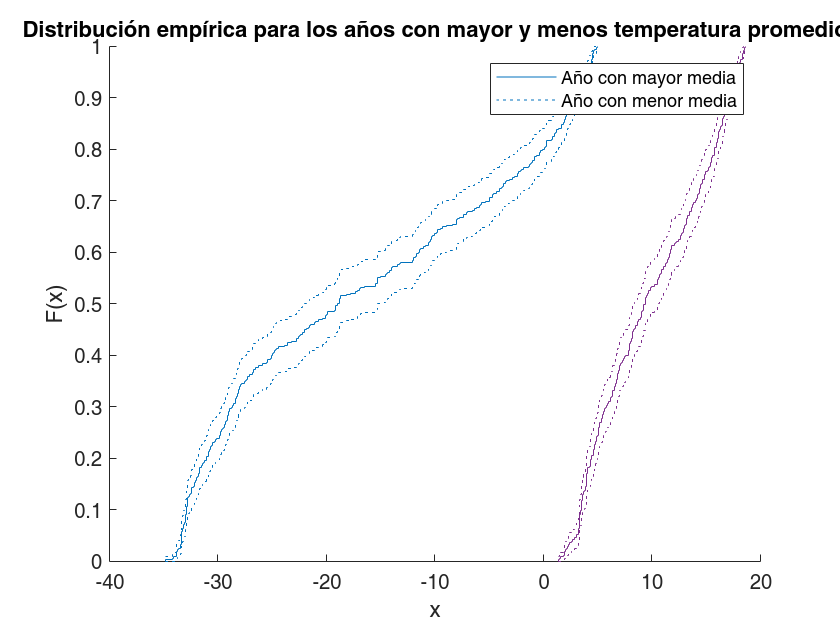

[minimum, minindex] = min(means);
[maximum, maxindex] = max(means);

clf
hold on
title("Distribución empírica para los años con mayor y menos temperatura " + ...
    "promedio")
xlabel("Temperatura")
ylabel("Probabilidad")
ecdf(Temps(:,minindex),'Bounds','on');
ecdf(Temps(:,maxindex),'Bounds','on');
legend({'Año con mayor media','Año con menor media'})

Punto 4

n = 100

n = 100

X = wblrnd(5, 0.8,n,1);
[F,t] = ecdf(X);
WeibulF = wblcdf(t,5,0.8);
min(abs(WeibulF-F))

ans = 3.8950e-05

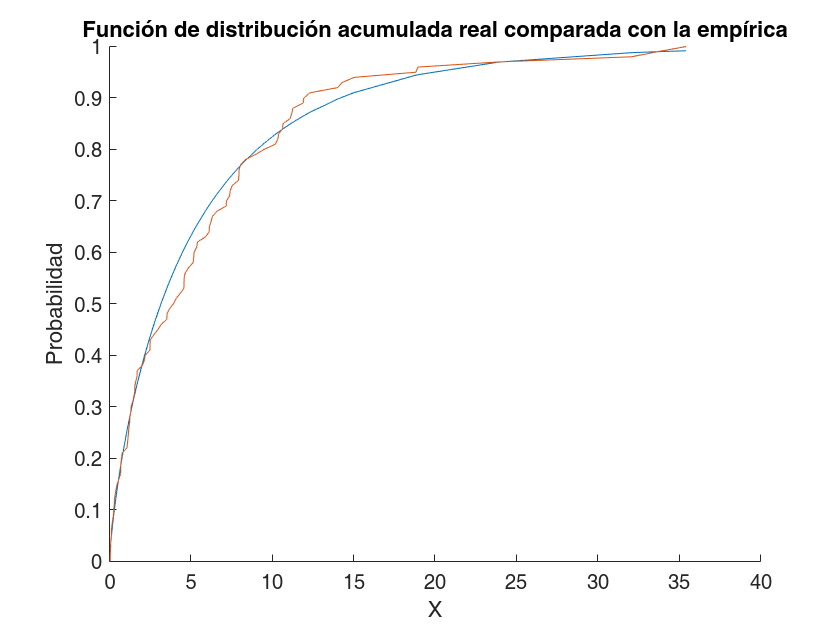

clf
hold on
plot(t,WeibulF)
plot(t,F)
title("Función de distribución acumulada real comparada con la empírica")
xlabel("X")
ylabel("Probabilidad")

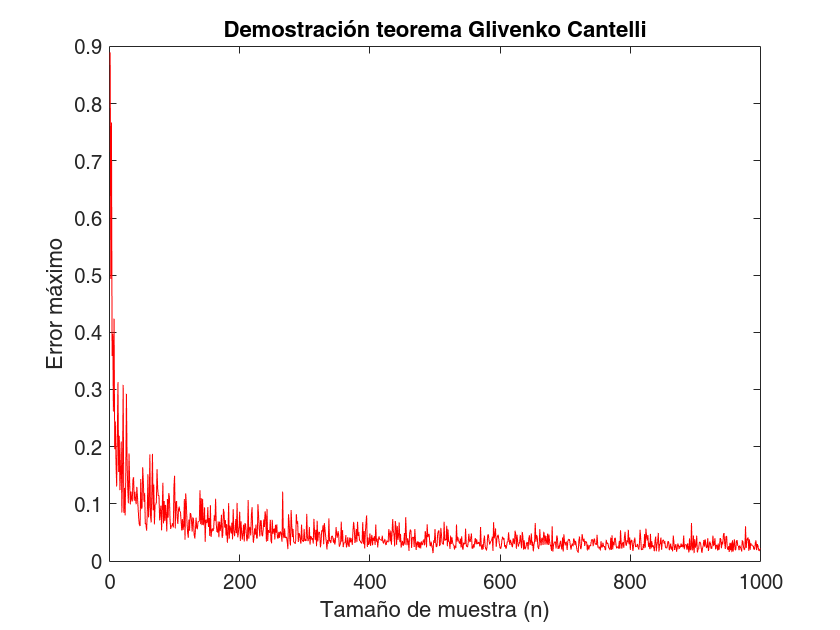

maxs = zeros(991,1);
for i = 1:1000
    X = wblrnd(5, 0.8,i,1);
    [F,t] = ecdf(X);
    WeibulF = wblcdf(t,5,0.8);
    maxs(i) = max(abs(WeibulF-F));
end
clf
plot(maxs,'r')
title("Demostración teorema Glivenko Cantelli")
xlabel("Tamaño de muestra (n)")
ylabel("Error máximo")

Punto 7

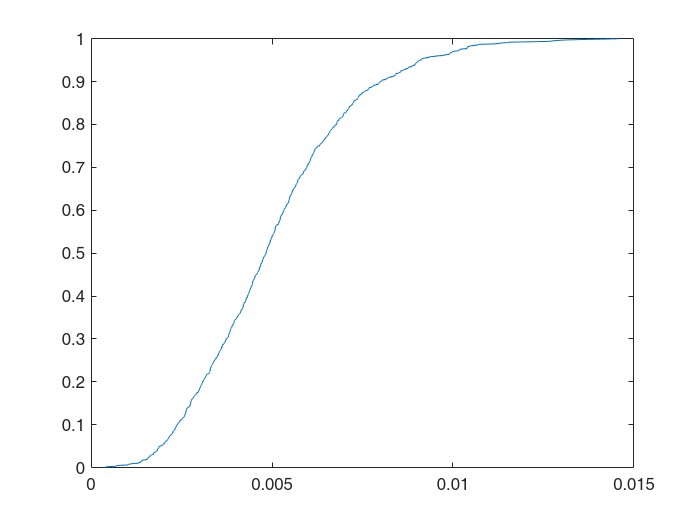

clf; clear all
syms i;
n=1000; N = 1000;
j = 5;

weibul = wblrnd(1,1,N,n);
weibulSort = sort(weibul);
ithValue = weibulSort(j,:);
[F,t] = ecdf(ithValue);

x = zeros(length(t),1);
for k=1:length(t)
    x(k) = double(symsum(nchoosek(n,i)*(wblcdf(t(k))^(i)*(1-wblcdf(t(k)))^(n-i)),i,j,n));
end

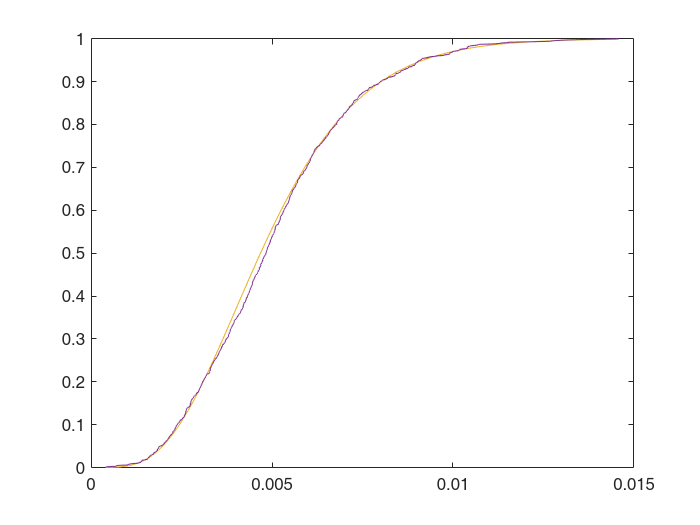

plot(t,x)
hold on
plot(t,F)

Punto 12

clf
[minimum, minindex] = min(means);
minYear = Temps(:,minindex);
maxTemp = max(minYear)

maxTemp = 5

m = bootstrp(1000,@max,minYear);
mean(m)

ans = 4.9323

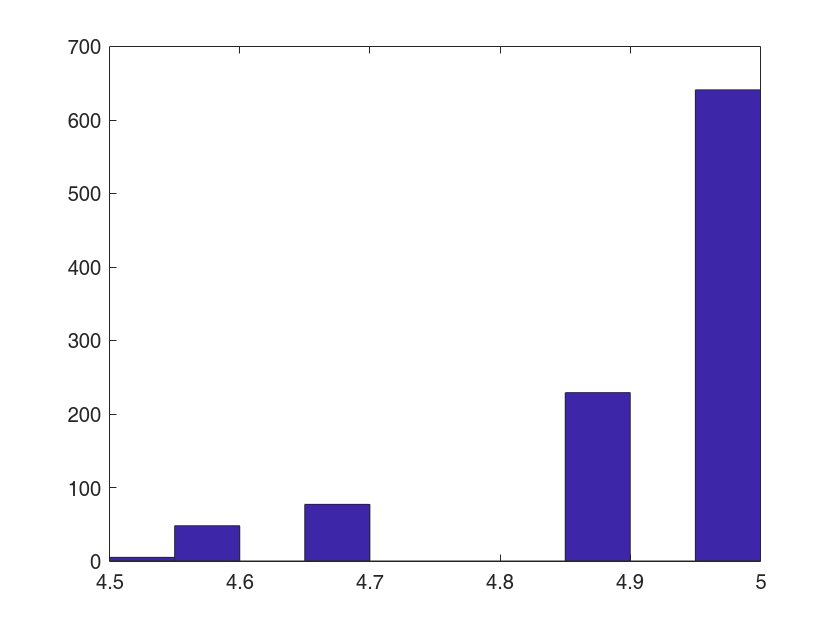

hist(m) %esperamos que se vea normal

%Varianza
std(m)

ans = 0.1165

%Intervalo de confianza
CIB = [prctile(m,2.5) prctile(m,97.5)] %Intervalo de confianza con bootstrap

CIB =     4.6000    5.0000


%Sesgo
jack = jackknife(@max,minYear);
n = length(minYear);

jbias = (n-1)*(mean(jack)-max(minYear))

jbias = -0.0997

Punto 13

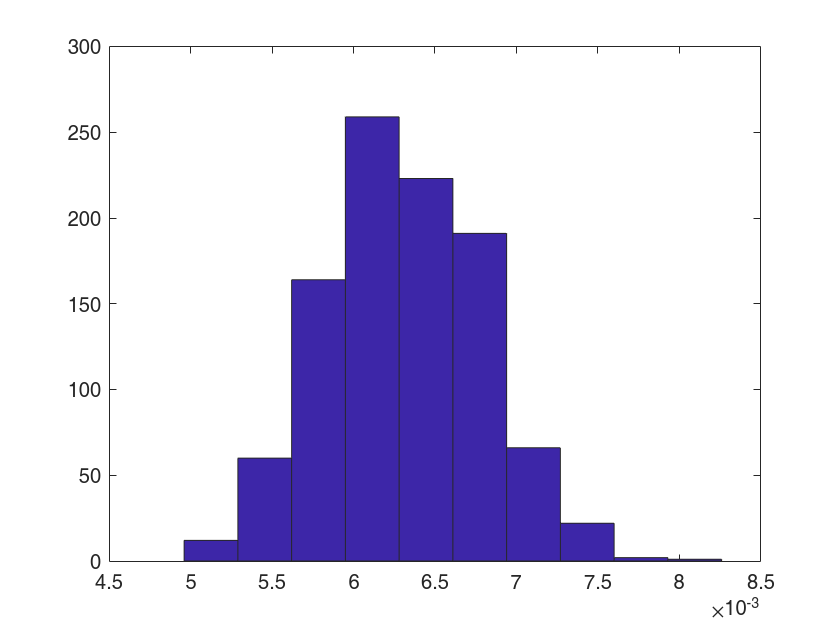

N = 1000;
n=10;
unif = rand(N,n);
mins = min(unif(:,:)');
m = bootstrp(1000,@var,mins);
hist(m)

mean(mins) %Sample mean value

ans = 0.0879

1/(n+1) %Expected mean value

ans = 0.0909

%Sesgo Varianza
m = jackknife(@min,mins);
bias = 1/(n+1) %Known minimum bias estimate

bias = 0.0909

jbias = (n-1)*(mean(m)-mean(mins)) %jackknife bias estimate

jbias = 0.0026

ans = 0.0018

bootstrp()